# ThermoeconomicModel demo

Analyze a system using ThermoeconomicModel function

#### **Create the Thermoeconomic Model**

the data file and create the model with some parameters. 

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
model=ThermoeconomicModel(filename,...
    'CostTables','ALL',...
    'DiagnosisMethod','WASTE_INTERNAL',...
    'Debug',false);

#### **Show the results for Reference State**

Print the result tables and show ICT and waste allocation graphs

model.showResults;


Flows Definition Table - REF

  Id Key  From     To       Type      
———————————————————————————————————————
   1 NG   ENV_R1   COMB_F1  RESOURCE  
   2 B1   ENV_R2   CMP_P1   RESOURCE  
   3 B2   CMP_P1   APH_P1   INTERNAL  
   4 B3   APH_P1   COMB_F1  INTERNAL  
   5 B4   COMB_P1  TRB_F1   INTERNAL  
   6 B5   TRB_F1   APH_F1   INTERNAL  
   7 B6   APH_F1   HRSG_F1  INTERNAL  
   8 B7   HRSG_F1  STCK_F1  INTERNAL  
   9 WC   TRB_P1   CMP_F1   INTERNAL  
  10 WN   TRB_P1   ENV_O1   OUTPUT    
  11 QV   HRSG_P1  ENV_O2   OUTPUT    
  12 QG   STCK_P1  ENV_W1   WASTE     


Productive Groups Definition Table - REF

  Id Key      Definition  Type      
—————————————————————————————————————
   1 COMB_F1  NG+B3       FUEL      
   2 COMB_P1  B4          PRODUCT   
   3 CMP_F1   WC          FUEL      
   4 CMP_P1   B2-B1       PRODUCT   
   5 TRB_F1   B4-B5       FUEL      
   6 TRB_P1   WC+WN       PRODUCT   
   7 APH_F1   B5-B6       FUEL      
   8 APH_P1   B3-B2       PRODUCT   
   9 HR

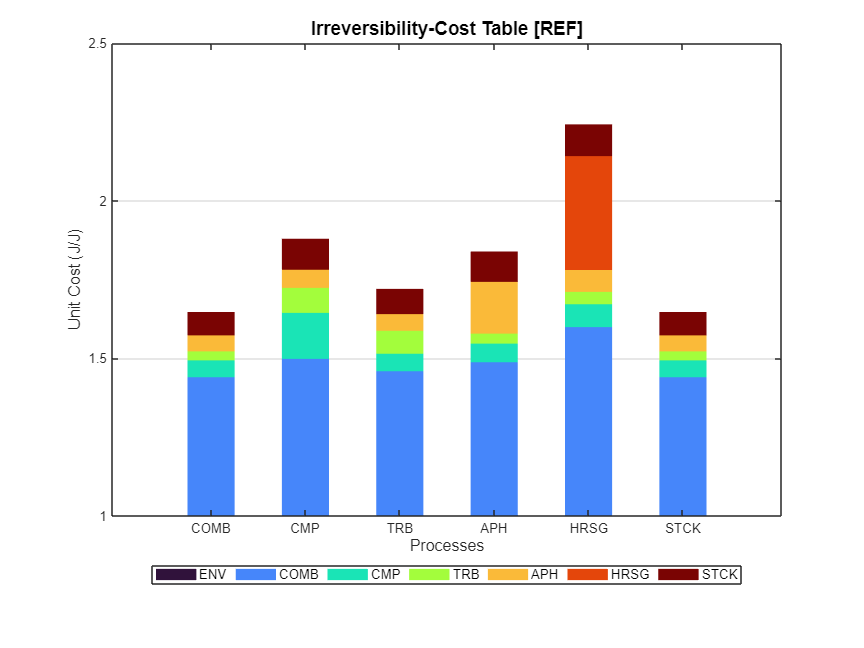

showGraph(model,cType.Tables.PROCESS_ICT);

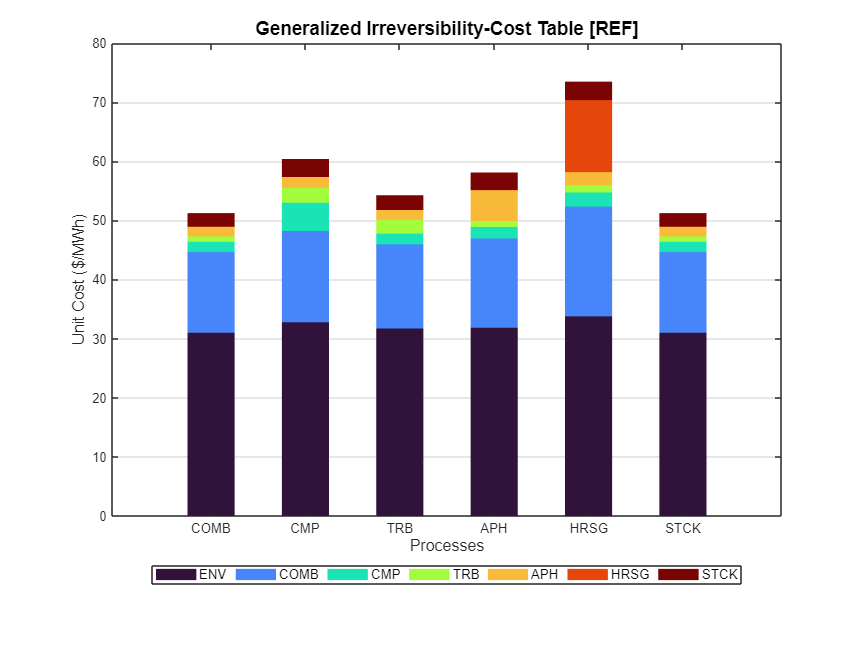

ShowGraph(model,'Graph',cType.Tables.PROCESS_GENERAL_ICT);

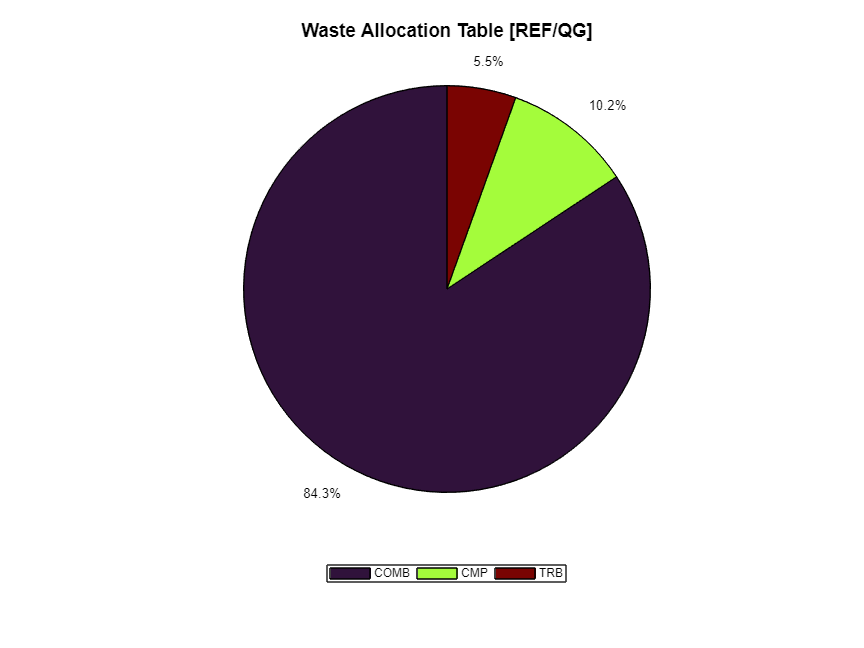

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION);

#### Save the Results

Save the results into a file, using diferent file types

save=false;
type="xlsx";
if save
    filename=strcat("model_result.",type);
    SaveResults(model,filename);
end

#### **Summary Results**

Select the summary option

#### Select the summary results

Options=convertCharsToStrings(model.summaryOptions);
option=convertStringsToChars(Options(4));
model.setSummary(option);
res=model.summaryResults;

#### Show  Results

Show all available tables

showResults(res)


Flows Exergy (MW) - SUMMARY

 key           REF      T1180      ETG87     ECMP84        RP8    PINCH15      CGAMR      noAPH
————————————————————————————————————————————————————————————————————————————————————————————————
 NG         72.465     73.327     73.600     73.297     72.283     72.465     72.465     97.896
 B1          0.000      0.000      0.000      0.000      0.000      0.000      0.000      0.000
 B2         28.651     29.507     29.337     29.196     27.863     28.651     28.651     25.141
 B3         50.339     50.896     51.926     51.018     51.048     50.339     50.339     25.141
 B4        102.530    103.462    104.971    103.813    103.163    102.530    102.530     91.046
 B5         38.810     38.735     40.230     39.295     40.324     38.810     38.810     31.211
 B6         14.784     15.021     15.213     15.137     14.597     14.784     14.784     31.211
 B7          2.122      2.230      2.156      2.112      2.228      2.353     14.784      1.429
 WC      

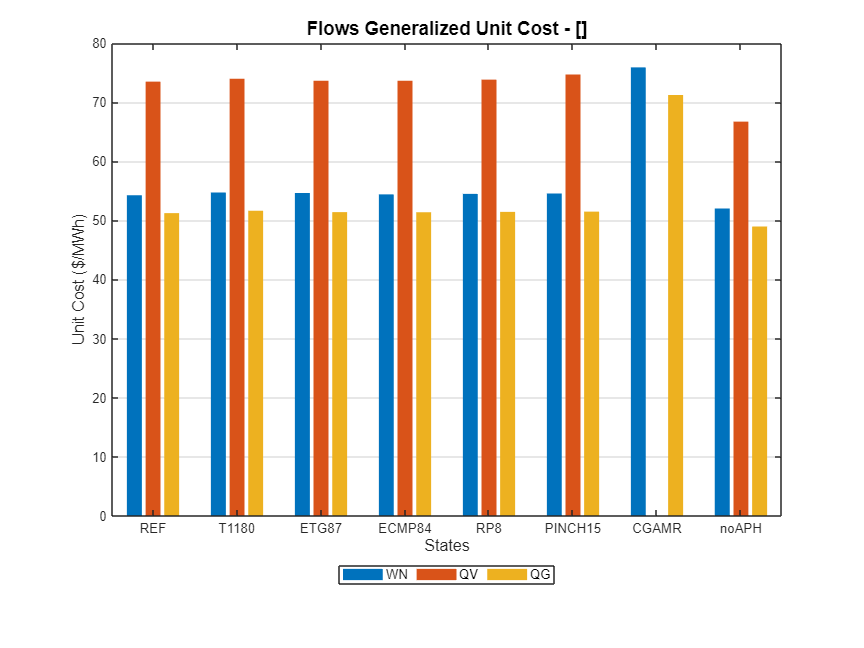

if model.isStateSummary
    showGraph(res,cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);
end

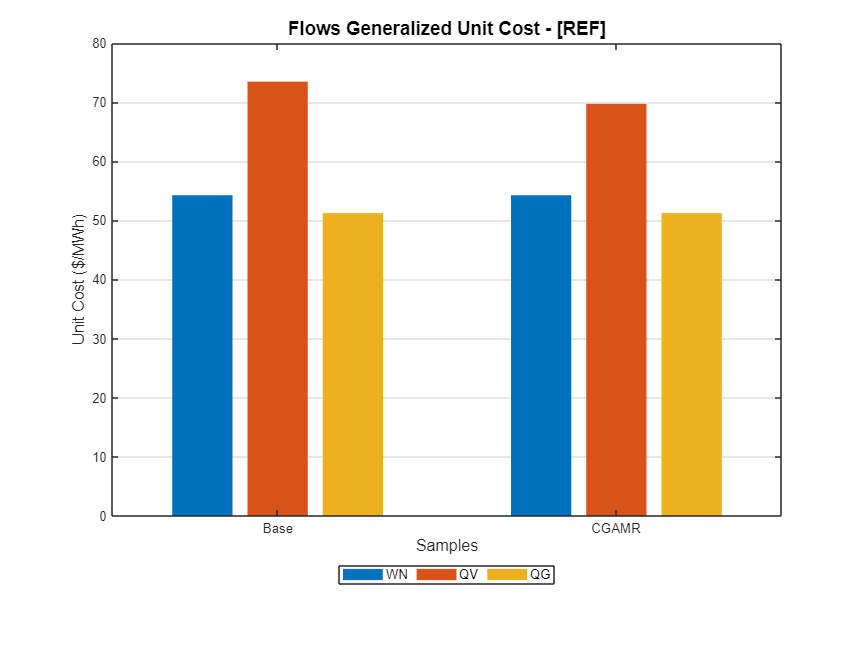

if model.isSampleSummary
    showGraph(res,cType.Tables.RSUMMARY_FLOW_GENERAL_UNIT_COST);
end

#### Diagnosis Analysis

Analyze a malfunction in the plant

States=convertCharsToStrings(model.StateNames);
state=convertStringsToChars(States(3));
model.setState(state);
model.summaryDiagnosis;

Fuel Impact:          1.1350 (MW)
Technical Saving:     0.4885 (MW)



showResults(model,cType.Tables.DIAGNOSIS);


Diagnosis Summary - ETG87

Key         MF(MW)      ΔI(MW)      ΔR(MW)     ΔPt(MW)     MF*(MW)     MR*(MW)    ΔPt*(MW)
———————————————————————————————————————————————————————————————————————————————————————————
COMB       -0.1970      0.2810      0.0000      0.0000      0.0873      0.0162      0.0000
CMP        -0.0007      0.0580      0.0000      0.0000     -0.0012     -0.0026      0.0000
TRB         0.2422      0.2770      0.0000      0.0000      0.3824      0.0187      0.0000
APH        -0.0068      0.0900      0.0000      0.0000     -0.0108     -0.0082      0.0000
HRSG        0.0024      0.1066      0.0000      0.2884      0.0038      0.0002      0.6492
STCK        0.0000      0.0000      0.0340      0.0000      0.0000      0.0000      0.0000
ENV         0.0400      0.8126      0.0340      0.2884      0.4614      0.0244      0.6492



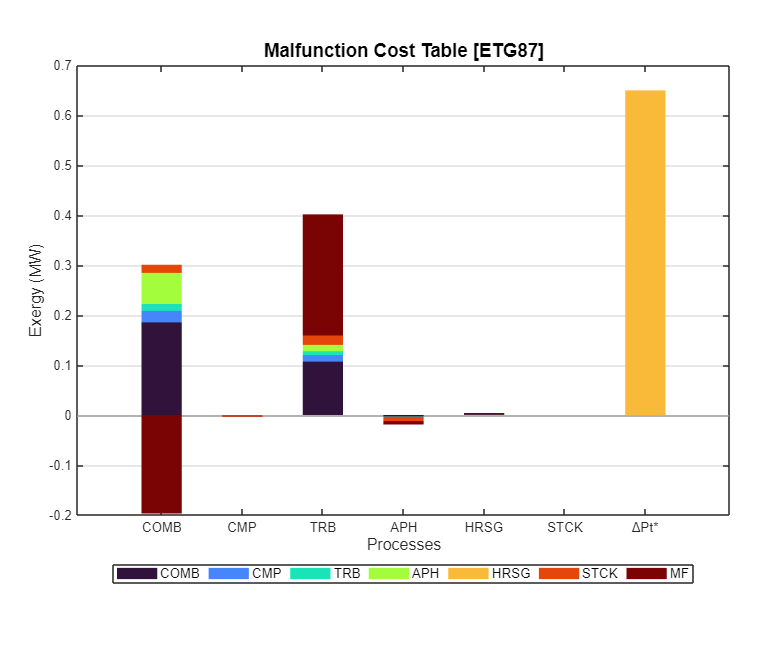

showGraph(model,cType.Tables.MALFUNCTION_COST,false);

#### **Recycling Analysis**

Select the model without IHE and analyse the capability of recycling

model.setRecycling(true);
setDiagnosisMethod(model,'NONE');
model.setState('noIHE');

showResults(model,cType.Tables.WASTE_RECYCLING_GENERAL);


Generalized Cost Recycling Analysis ($/MWh) - [ETG87/]

 Recycle (%)            WN         QV         QG
—————————————————————————————————————————————————
      0            54.6362    73.6124    51.3911
     10            54.3735    73.2841    51.1500
     20            54.1134    72.9589    50.9111
     30            53.8556    72.6367    50.6745
     40            53.6002    72.3175    50.4400
     50            53.3471    72.0013    50.2077
     60            53.0964    71.6879    49.9775
     70            52.8480    71.3774    49.7494
     80            52.6018    71.0697    49.5234
     90            52.3579    70.7648    49.2995
    100            52.1161    70.4627    49.0775



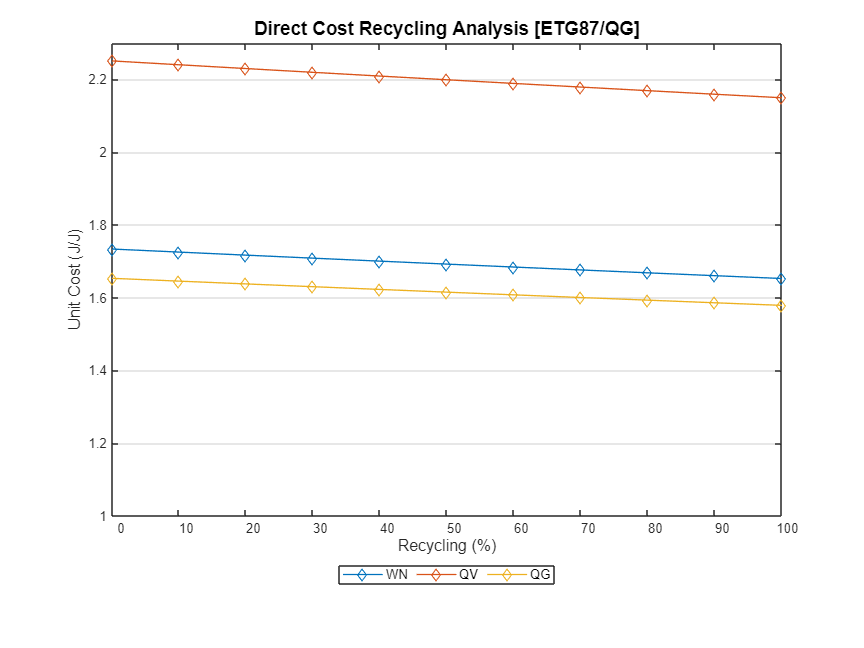

showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);

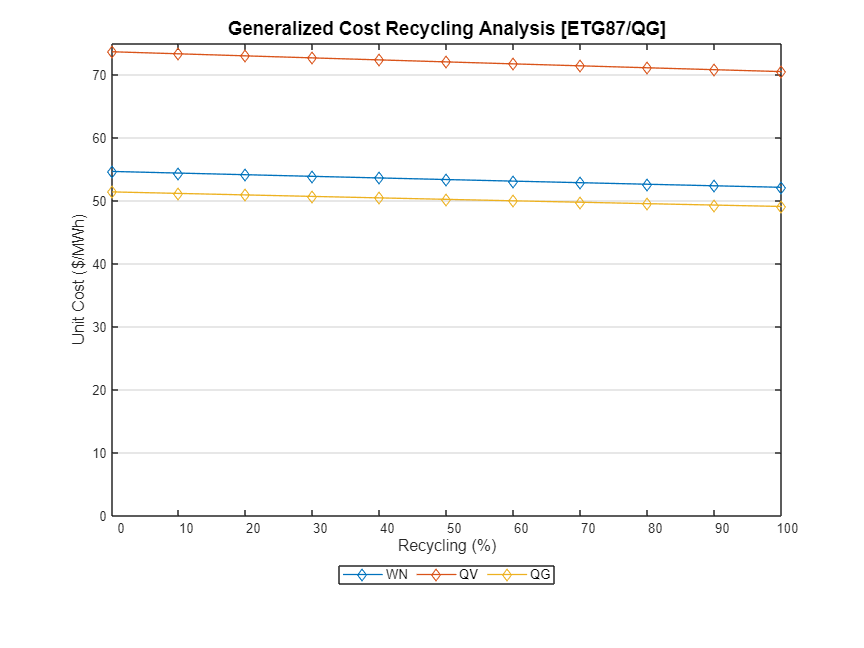

showGraph(model,cType.Tables.WASTE_RECYCLING_GENERAL);

#### Additional Help

help ThermoeconomicModel

 ThermoeconomicModel - Creates a cThermoeconomicModel object from a data model file 
    This function creates a cThermoeconomicModel object. Once the object has been created, 
    all the functions available in the class can be used, 
    allowing you to obtain all the results of a thermoeconomic analysis interactively.
 
    Syntax
      model = ThermoeconomicModel(filename,Name,Value)
 
    Input Arguments
      filename - Name of the file with the data mode
 
    Name-Value Arguments
      ReferenceState - Reference state name. If it is not defined, first state is taken.
        char array | string
      State - Operation state name. If it is not defined, first state is taken.  
        char array | string
      ResourceSample - Resource Sample name. If it is not defined, first sample is taken
        char array | string
      CostTables - Cost Tables output
        'DIRECT' Direct Exergy Cost Tables only
        'GENERALIZED' Generalized Cost Tabl